# Linear Control Design II - Group Work Problem Module 13 Solution


$$\matrix{\text{Jakob\,Mahler\,Hansen} \cr \text{Department\,of\,Electrical\,Engineering} \cr \text{September,\,2011} \cr \text{Thomas\,Thougaard\,Paulsen} \cr \text{September,\,2017}}$$


## Description

This group work module deals with the design of a full state feedback controller for the model of the aircraft analysed in Group Work Module 7 (the SISO model).

% Define system matrices:
A = [-0.0558 -0.9968  0.0802  0.0415;
      0.598  -0.115  -0.0318  0;
     -3.050   0.388  -0.4650  0;
      0       0.0805  1       0]

A =    -0.0558   -0.9968    0.0802    0.0415
    0.5980   -0.1150   -0.0318         0
   -3.0500    0.3880   -0.4650         0
         0    0.0805    1.0000         0


B = [0.00729; -0.475; 0.153; 0]

B =     0.0073
   -0.4750
    0.1530
         0


C = [0 1 0 0]

C =      0     1     0     0


D = 0;

**Problem 1**

Transform the continuous time model given in Module 7 into the controller canonical form.

**Solution****:**

First of all, the characteristic polynomial associated to the **A** matrix is found with the *poly()* function as.


$$P_{ch,\textbf{A}}=det(\lambda\textbf{I}-\textbf{A})=\lambda^4+0.6358\lambda^3+0.9389\lambda^2+0.5116\lambda+0.0037$$


Then the **P** matrix can be calculated as in Eq. (3.353) on page 160 of the textbook.

Since the SISO system is controllable, it can be shown that all the **p** vectors are linearly independent, and therefore the inverse of **P** exists.

The **P** matrix is therefore given by


$$\textbf{P}=\left[\matrix{-0.0077&0.2169&0.4900&0.0073\cr-0.0563&-0.1187&-0.2479&-0.4750\cr0.0045&-1.3631&-0.1804&0.1530\cr-1.3726&-0.2004&0.1148&0}\right]$$


The system matrices in controller canonical form can be calculated from (3.358), (3.361), (3.362) and (3.363) in the textbook by using the **P** matrix.


$$\textbf{A}_{CC}=\textbf{P}^{-1}\textbf{A}\textbf{P}=\left[\matrix{0&1&0&0\cr0&0&1&0\cr0&0&0&1\cr-0.0037&-0.5116&-0.9389&-0.6358}\right]$$



$$\textbf{B}_{CC}=\textbf{P}^{-1}\textbf{B}=\left[\matrix{0\cr0\cr0\cr1}\right]$$



$$\textbf{C}_{CC}=\textbf{C}\textbf{P}=\left[\matrix{-0.0563&-0.1187&-0.2479&-0.4750}\right]$$



$$\textbf{D}_{CC}=\textbf{D}=\left[0\right]$$


% In Matlab, the useage of the poly() function is shown
chapo = poly(A)

chapo =     1.0000    0.6358    0.9389    0.5116    0.0037



% Here the P matrix is defined from determining the p vectors
p1 = B;
p2 = A*p1 + chapo(2)*p1;
p3 = A*p2 + chapo(3)*p1;
p4 = A*p3 + chapo(4)*p1;
P = [p4 p3 p2 p1]

P =    -0.0077    0.2169    0.4900    0.0073
   -0.0563   -0.1187   -0.2479   -0.4750
    0.0045   -1.3631   -0.1804    0.1530
   -1.3726   -0.2004    0.1148         0



% By using the P matrix the system can be written in the controller
% canonical form
Acc = P^(-1)*A*P

Acc =    -0.0000    1.0000    0.0000   -0.0000
    0.0000    0.0000    1.0000    0.0000
   -0.0000    0.0000    0.0000    1.0000
   -0.0037   -0.5116   -0.9389   -0.6358


Bcc = P^(-1)*B

Bcc =    -0.0000
         0
   -0.0000
    1.0000


Ccc = C*P

Ccc =    -0.0563   -0.1187   -0.2479   -0.4750


Dcc = D

Dcc =      0


**Problem 2**

It is desired to assign the eigenvalues through state feedback such that the damping ratio for the least damped eigenvalues is increased to approximately 0.7, and such that natural frequencies and time constants are approximately unchanged. A reasonable assignment could be:


$$\lambda = \left\{\matrix{-0.01 \cr -0.6 \cr -0.5\pm0.5j} \right.$$


Find the gain matrix **K** for the controller


$$u = -\textbf{Kx}+r$$


by applying the method from Section 4.3.1 in the textbook. Check that the eigenvalues of the closed-loop system have been assigned as desired.

**Solution****:**

The gain matrix **K** for the controller can be found by considering the closed loop characteristic polynomial. Including the controller into the system the close-loop system matrix becomes


$$\textbf{A}_{\textbf{K}CC}=\textbf{A}_{CC}-\textbf{B}_{CC}\textbf{K}_{CC}$$


and its characteristic polynomial is


$$P_{ch,\textbf{A,K}CC}=\prod_{i=1}^n(\lambda-\lambda_{cl,i})=\lambda^4+1.6100\lambda^3+1.1160\lambda^2+0.3110\lambda+0.0030$$


where $\lambda_{cl,i}$ is the i'th desired eigenvalue.

The elements in the feedback gain matrix are found as the difference between the coefficients of the open and closed loop characteristic polynomials, that is


$$\textbf{K}_{CC}=\left[\matrix{\alpha_0-a_0&\alpha_1-a_1&\alpha_2-a_2&\alpha_3-a_3}\right]$$



$$\textbf{K}_{CC}=\left[\matrix{-0.0007&-0.2006&0.1771&0.9742}\right]$$


where $\alpha_i$ and $a_i$ are the coefficients of the i'th order part of the closed and the open loop characteristic polynomials, respectively.

To get the gain matrix for the original system the $\textbf{K}_{CC}$ matrix is transformed from canonical form back to the original system coordinates by using the inverse of **P**


$$\textbf{K}_{1}=\textbf{K}_{CC}\textbf{P}^{-1}$$



$$\textbf{K}_1=\left[\matrix{-0.589&-1.9909&0.2145&0.0862}\right]$$


The controller $\textbf{K}_1$ is inserted in the negative feedback loop, and it changes the input to the system as


$$u = -\textbf{K}_1\textbf{x}+r$$


To check that the desired eigenvalues have been assigned correctly the eigenvalues of the closed loop system are calculated. This is achieved with the *eig()* function


$$\lambda_{cl}=\text{eig}(\textbf{A}-\textbf{BK}_1) = \left\{\matrix{-0.01 \cr -0.6 \cr -0.5-0.5j\cr-0.5+0.5j} \right.$$


The desired eigenvalues are obtained: the system damping is now larger, leading to smaller oscillations.

% In Matlab, the polynomium leading to the desired eigenvalues is
% calculated from the function poly()
alpha = poly([-0.01 -0.6 -0.5+0.5*i -0.5-0.5*i])

alpha =     1.0000    1.6100    1.1160    0.3110    0.0030


% Controller gains in controller canonical form
Kcc = fliplr(alpha-chapo)

Kcc =    -0.0007   -0.2006    0.1771    0.9742         0


% Controller gains for the states
K = Kcc(1:4)*P^(-1)

K =    -0.5869   -1.9909    0.2145    0.0862



% Checking the closed loop eigenvalues
eig(A-B*K)

ans =   -0.0100 + 0.0000i
  -0.5000 + 0.5000i
  -0.5000 - 0.5000i
  -0.6000 + 0.0000i


**Problem 3**

Add the controller to the Simulink open-loop model and carry out a simulation with the function shown on Figure 1 as input to the closed-loop system. Plot the states, the output and the rudder angle.

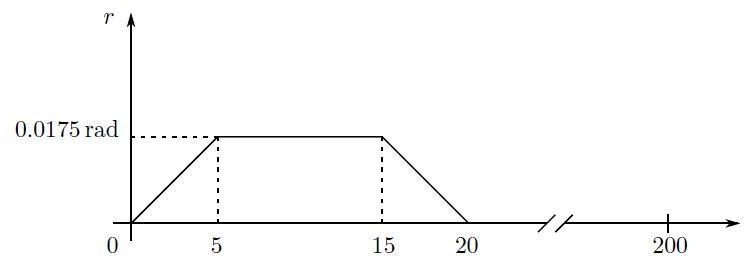


$$Figure\,1: Input\,signal\,to\,the\,closed\,loop\,system.$$


**Solution****:**

The controller is placed in the negative feedback loop from the states to a summation point at the input of the system. See Figure 2 for the Simulink implementation.

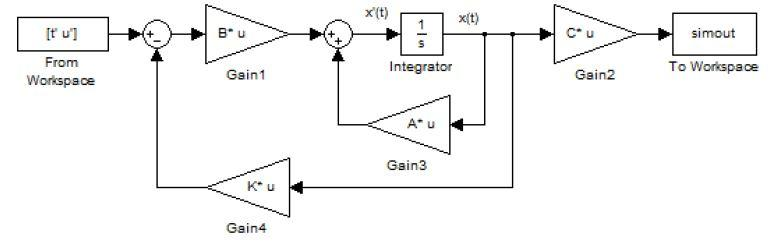


$$Figure\,2: Block\,diagram\,with\,the\,designed\,controller\,\textbf{K}_1.$$


The response of the system is tested with and without the controller to compare its characteristics.

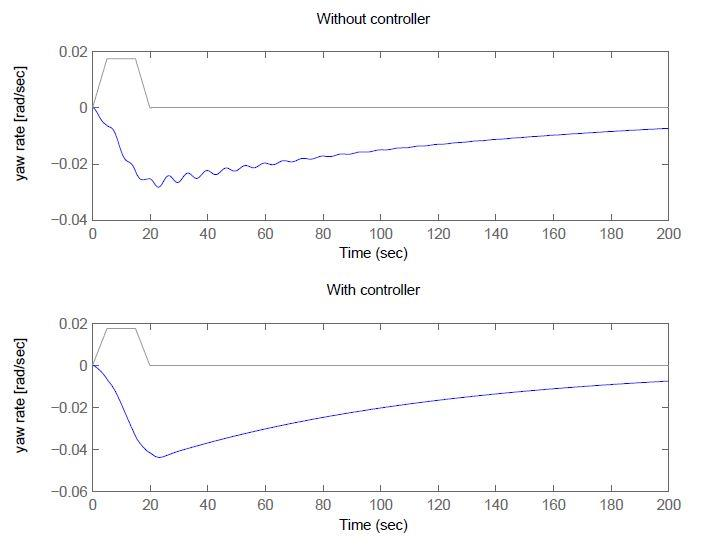


$$Figure\,3: Response\,of\,the\,system\,without\,(top)\,and\,with\,(bottom)\,controller\,\textbf{K}_1.$$


Figure 3 shows that the controlled response is less oscillatory, giving more pleasant flight conditions. On the other hand, the magnitude of the response is almost doubled.

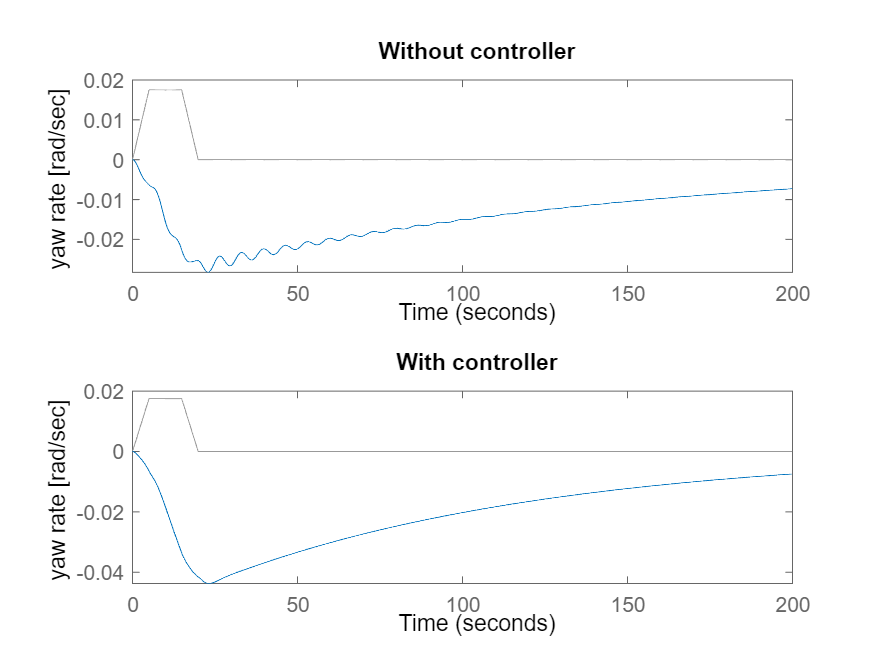

% Simulation of state responses
t = 0:.1:199.9; % Time vector
ut1 = (0:50) * 0.0175/50; % Rising input
ut2 = ones(1,98) * 0.0175; % Constant input
ut3 = (0:50) * (-0.0175/50) + 0.0175; % Decending input
ut4 = zeros(1,1800); % Zero input
u = [ut1 ut2 ut3 ut4];

figure(1)
subplot(2,1,1), lsim(A,B,C,D,u,t,[0 0 0 0]');
title('Without controller');
ylabel('yaw rate [rad/sec]');
subplot(2,1,2), lsim(A-B*K,B,C,D,u,t,[0 0 0 0]');
title('With controller');
ylabel('yaw rate [rad/sec]');

**Problem 4**

Repeat Problems 2 and 3 with the largest time constant decreased by a factor 50 and by applying Ackermann's formula (the Matlab's function is called *acker()*). The Ackermann's formula has to be applied to the original model.

**Solution****:**

The largest time constant is desired to be decreased by a factor 50, to obtain a faster system's response. Hence, the new desired eigenvalues of the system are


$$\lambda = \left\{\matrix{-0.01\cdot50 \cr -0.6 \cr -0.5\pm0.5j} \right.$$


The new pole placement is carried out with the Matlab *acker()* function. The function calculates the feedback gain matrix $\textbf{K}_2$, such that the SISO system with the feedback law


$$u=-\textbf{K}_2\textbf{x}$$


has closed loop poles at the desired positions. The gain matrix is


$$\textbf{K}_2=\left[\matrix{0.4474&-3.0480&0.0860&0.0163}\right]$$


With this new controller gain plugged into the system the maneuver is accomplished in much less time, as shown in Figure 4.

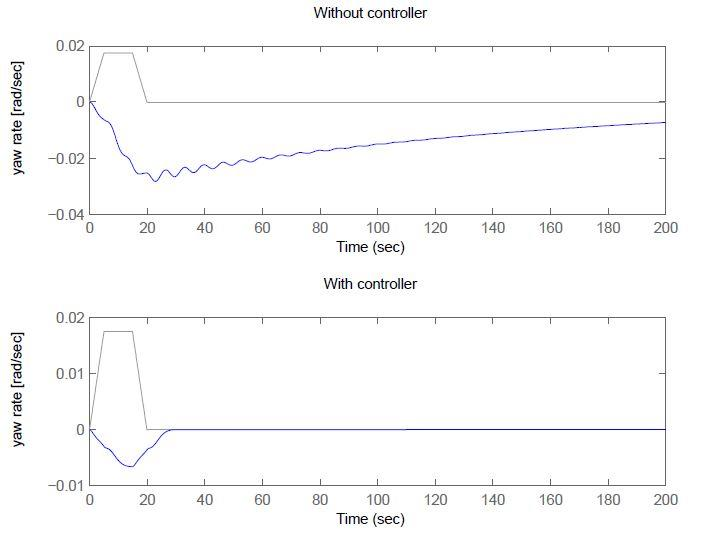


$$Figure\,4:Response\,of\,the\,system\,without\,(top)\,and\,with\,(bottom)\,controller\,\textbf{K}_2.$$


Note that the magnitude of the response is now smaller than for the nonlinear model.

eigClose = [-0.01*50 -0.6 -0.5+0.5*i -0.5-0.5*i];
KQ4 = acker(A,B,eigClose)

KQ4 =     0.4474   -3.0480    0.0860    0.0163


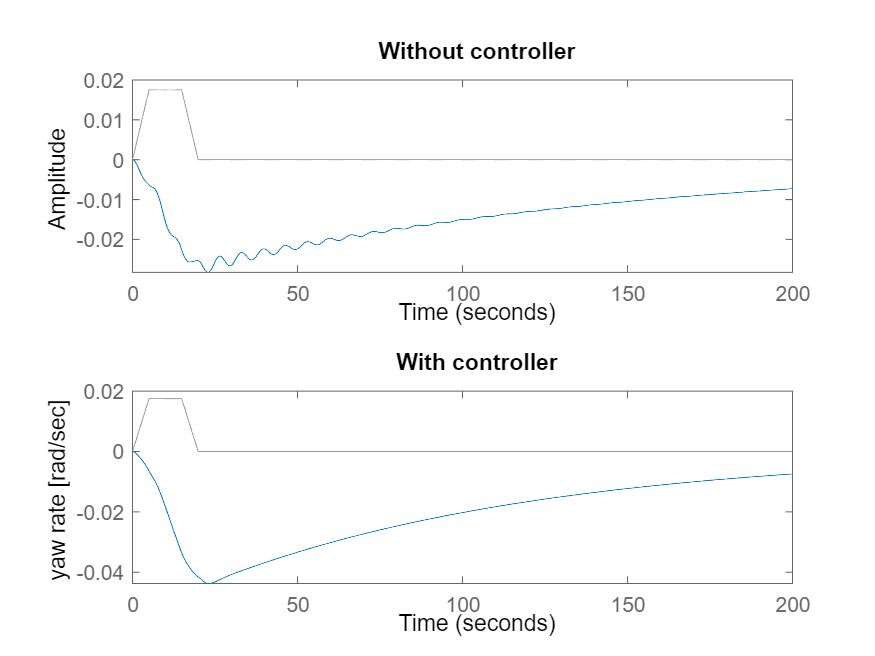


figure(2)
subplot(2,1,1), lsim(A,B,C,D,u,t,[0 0 0 0]')
title('Without controller');

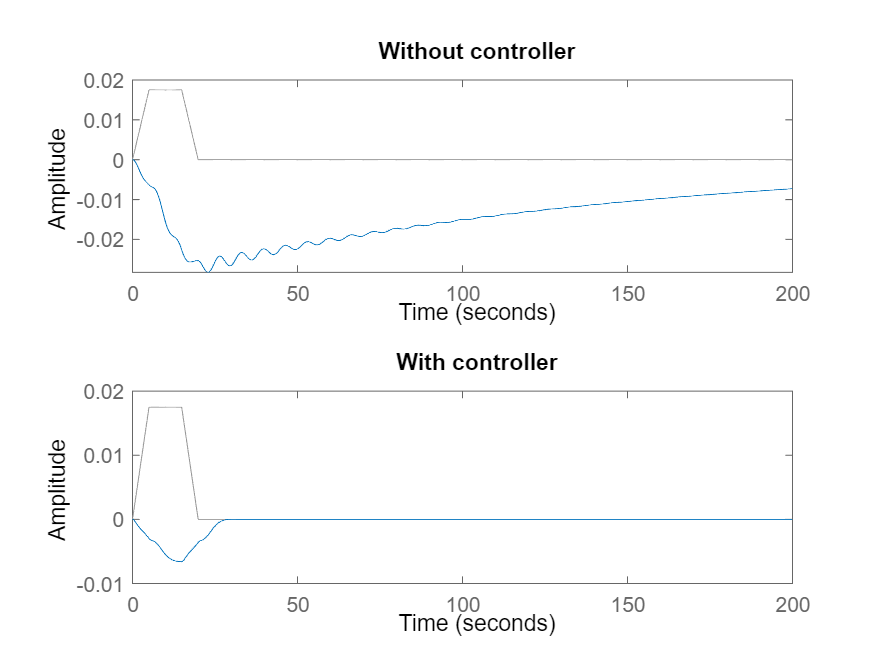

subplot(2,1,2),lsim(A-B*KQ4,B,C,D,u,t,[0 0 0 0]')
title('With controller');

**Problem 5**

Repeat Problem 4 for a discrete time controller. Do not forget to convert the eigenvalues to the discrete domain. The discrete time controller must be tested together with the continuous time plant. To enable interaction between the continuous and discrete time parts of the control loop do not forget to insert digital-to-analogue (DAC) and analogue-to-digital (ADC) converters into the system. The DAC is usually a zero-order hold, and such a block is available in Simulink's discrete library. The ADC is implemented in Simulink as a discrete transfer function (same library) with 1 as numerator and denominator, as shown in Figure 5. All discrete blocks use the parameter *Sample Time*, which has to be chosen in a suitable manner.

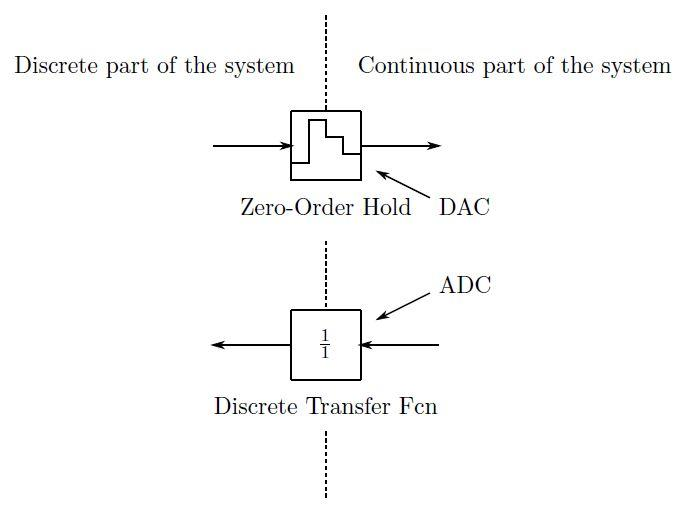


$$Figure\,5: Simulink\,discretization\,blocks.$$


**Solution****:**

To discretize the model a DAC (Digital to Analog Converter in the form of a Zero-order hold) and a ADC (Analog to Digital Converter in the form of a Discrete Transfer function) are inserted as seen on Figure 6.

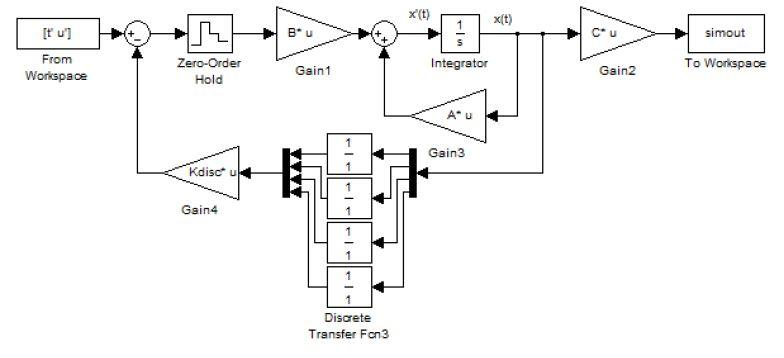


$$Figure\,6: Block\,diagram\,of\,the\,discrete\,system\,with\,controller.$$


The sample time of the system needs to be speciffied in the DAC and ADC blocks. The ADC only works for one input to one output, so the system lines are disassembled with a demux-block. When calculating gain matrix for the discrete system the system matrices as well as the eigenvalues needs to be converted to discrete time. First of all a sample time needs to be chosen, therefore $Ts=0.1$ is selected.

The discrete matrices are found with the Matlab *c2d()* function.


$$\textbf{F}=\text{e}^{\textbf{A}*Ts}=\left[\matrix{0.9902&-0.09852&0.008162&0.004133\cr0.05968&0.9855&-0.002846&0.000124\cr-0.2956&0.05251&0.9533&-0.00062\cr-0.0147&0.0104&0.09766&1}\right]$$



$$\textbf{G}=\int_0^{Ts}\text{e}^{\textbf{A}Ts}\textbf{B}\text{d}t=\left[\matrix{0.003138\cr-0.04718\cr0.01369\cr0.0005229}\right]$$


The eigenvalues of the discrete time system are


$$\lambda_{F}=\text{e}^{\lambda_ATs}= \left\{\matrix{0.9512 \cr 0.9418 \cr 0.9500+0.0475i\cr-0.9500+0.0475i} \right.$$


The discrete controller gain matrix is found using *acker()* function, as in the continuous case,


$$\textbf{K}_{disc}=\left[\matrix{0.3155&-2.8363&0.0850&0.0159}\right]$$


The responses for the system with and without the controller are depicted in Figure 7.

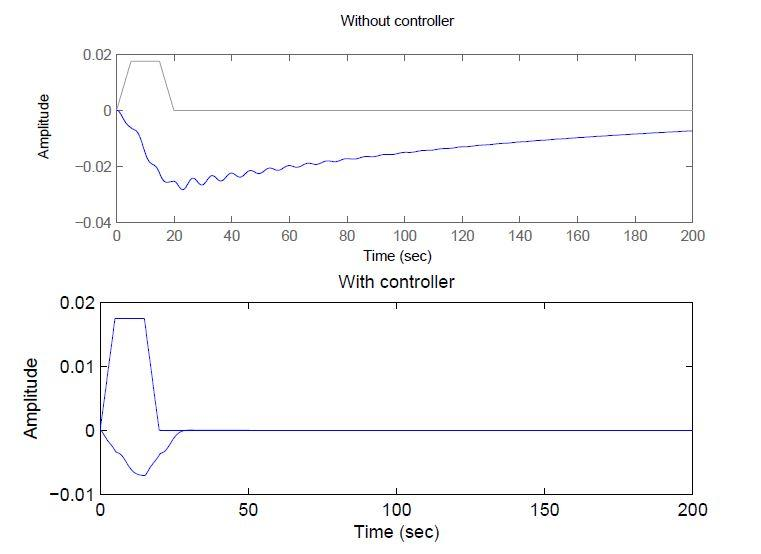


$$Figure\,7: The\,responses\,of\,the\,discrete\,system\,with\,and\,without\,the\,controller.$$


Ts = 0.1;
F = expm(A*Ts); % Matrix product in exponent
sys = c2d(ss(A,B,C,D),Ts,'zoh')

sys =
 
  A = 
              x1         x2         x3         x4
   x1     0.9902   -0.09852   0.008162   0.004133
   x2    0.05968     0.9855  -0.002846   0.000124
   x3    -0.2956    0.05251     0.9533   -0.00062
   x4    -0.0147     0.0104    0.09766          1
 
  B = 
              u1
   x1   0.003138
   x2   -0.04718
   x3    0.01369
   x4  0.0005229
 
  C = 
       x1  x2  x3  x4
   y1   0   1   0   0
 
  D = 
       u1
   y1   0
 
Sample time: 0.1 seconds
Discrete-time state-space model.



G = get(sys,'b')

G =     0.0031
   -0.0472
    0.0137
    0.0005


eigDisc = exp(eigClose*Ts)

eigDisc =    0.9512 + 0.0000i   0.9418 + 0.0000i   0.9500 + 0.0475i   0.9500 - 0.0475i


Kdisc = acker(F,G,eigDisc)

Kdisc =     0.3155   -2.8363    0.0850    0.0159


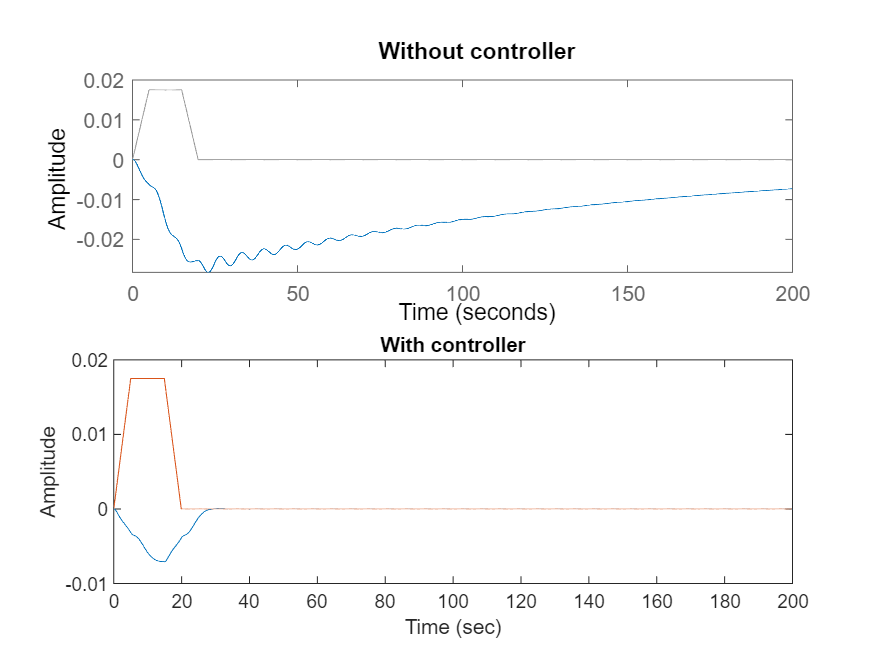

figure
subplot(2,1,1), lsim(sys,u,t,[0 0 0 0]')
title('Without controller');
sim('Q5');
subplot(2,1,2), plot(simout.time,simout.signals.values);
hold on
plot(t,u);
hold off;
title('With controller');
xlabel('Time (sec)');
ylabel('Amplitude');

**Problem 6**

Compare the system responses from Problem 4 and 5, and discuss the effect of discretization on the system performance.

**Solution****:**

The response of the discrete system with controller resembles the continuous system with controller.